syms t xk xn;
t0=sym(pi/4)

$$t0 = \frac{\pi }{4}$$

x=sqrt(2)*cos(t)^3

$$x = \sqrt{2}\,{\cos\left(t\right)}^{3}$$

y=sqrt(2)*sin(t)^3

$$y = \sqrt{2}\,{\sin\left(t\right)}^{3}$$

% Составить уравнения касательной и нормали к астроиде

ezplot(x,y)
hold on

Dx=diff(x)

$$Dx = -3\,\sqrt{2}\,{\cos\left(t\right)}^{2}\,\sin\left(t\right)$$

Dy=diff(y)

$$Dy = 3\,\sqrt{2}\,\cos\left(t\right)\,{\sin\left(t\right)}^{2}$$


Dyx=Dy/Dx

$$Dyx = -\frac{\sin\left(t\right)}{\cos\left(t\right)}$$


x0=subs(x,t,t0)

$$x0 = \frac{1}{2}$$

y0=subs(y,t,t0)

$$y0 = \frac{1}{2}$$

plot(x0,y0,'ro')

Dyx0=subs(Dyx,t,t0)

$$Dyx0 = -1$$


% Касательная
yk=y0+Dyx0*(xk-x0)

$$yk = 1-\mathrm{xk}$$

ezplot(yk,[-2,2])

% Нормаль
yn=y0-1/Dyx0*(xn-x0)

$$yn = \mathrm{xn}$$

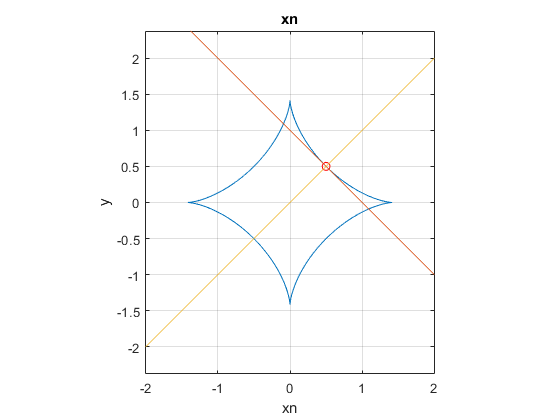

ezplot(yn,[-2,2])
grid on
hold off